Histogram Equalization:

In this problem, we are required to understand and utilize histogram equalization on the grayscale images provided to us.

NOTE: Image GrayScaleMRI.mat is working fine with the load function of Matlab but image geospatialImage.mat is throwing "Unrecognized field name "geospatialImage". " error while trying to load so I have commented that load command for geospatialImage.mat file.

Reading our image from provided .mat files

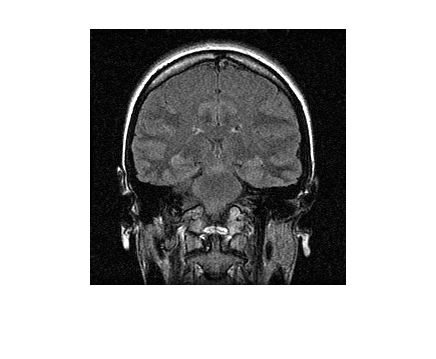

Gmr = load("E:\Fall 2022 Courses\ECE 6337\ECE 6337 project\GrayScaleMRI.mat"); %loading our GrayScaleMRI.mat image using in-built function load() in Matlab.
imshow(Gmr.GrayScaleMRI) %displaying our image using in-built function imshow() in Matlab.

%Gspc = load("E:\Fall 2022 Courses\ECE 6337\ECE 6337 project\geospatialImage.mat");
%imshow(Gspc.geospatialImage)
%I = imread("E:\Fall 2022 Courses\ECE 6337\ECE 6337 project\GrayScaleMRI.tif");

Displaying our image from loaded .mat files 

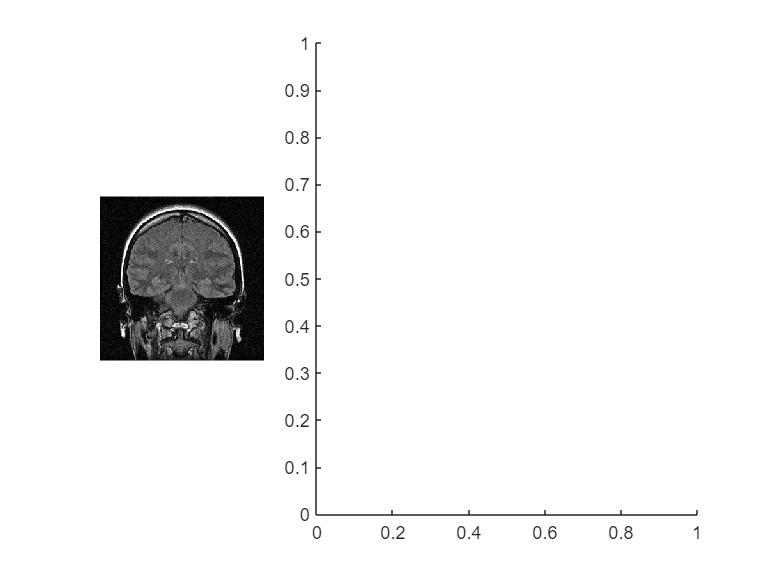

figure('Name','Normal Image Histogram') %Naming our image display
subplot(1,3,1)
imshow(Gmr.GrayScaleMRI) %displaying loaded image once again
subplot(1,3,2:3)

Here I am displaying histogram of my normal image and we can see that this histogram is not equalized and most of the values are either centered near 100 or below 50.

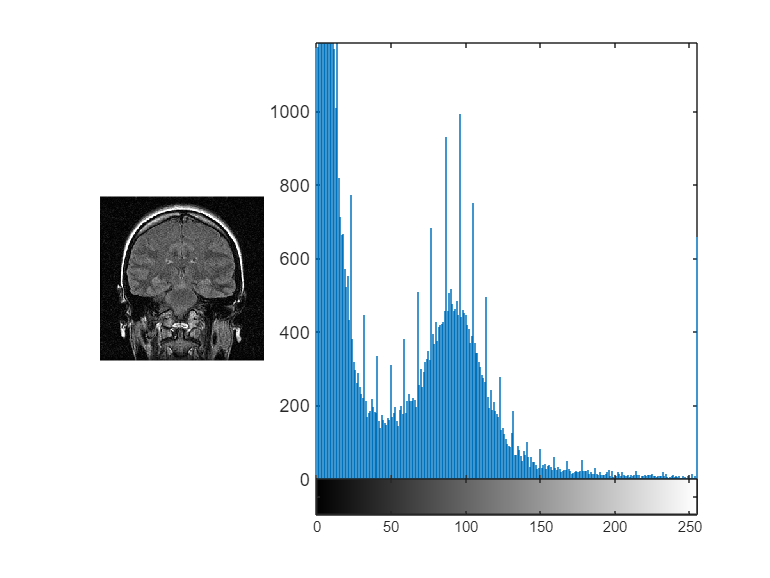

imhist(Gmr.GrayScaleMRI)

Now we will feed our loaded image to histeq() function of matlab to equalize its histogram. Also not that default bin size for histeq() function is 64. So here we are using default bin size.

Eq_MRI = histeq(Gmr.GrayScaleMRI);

After equalizing the histogram we will then display the contrast-adjusted image and its new histogram.

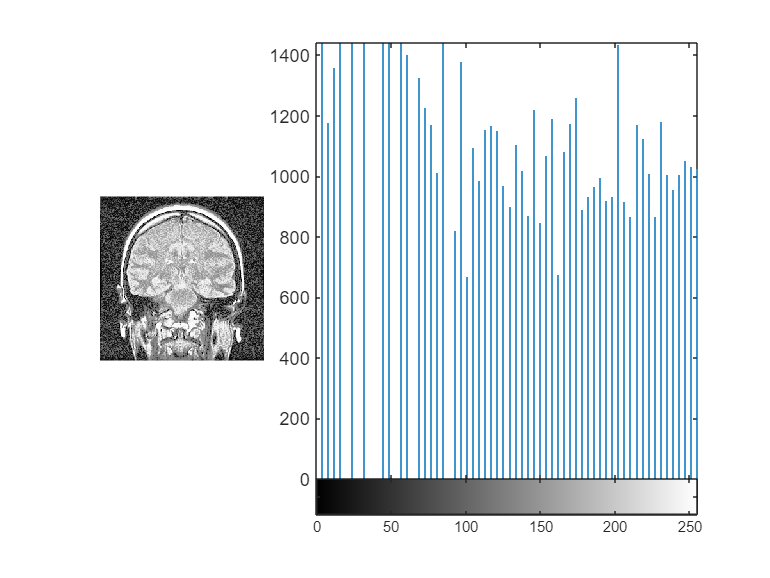

figure('Name','Histogram Equalization with Default 64 Number of Bins')
subplot(1,3,1)
imshow(Eq_MRI)
subplot(1,3,2:3)
imhist(Eq_MRI)

As we can see the image contrast is displaying a decent improvement in pixel intensity and also the corresponding histogram plot of the image is equalized. 

Additional Work: Let's suppose if we don't want to go with default bin size of 64 to adjust contrast then we can specify our customized different number of bins to adjust contrast of the displayed image.

nbins_sb = 50

nbins_sb = 50

Try adjusting the number of bins using the slider scale of nbins_sb variable to see how the histogram equalization changes the contrast of image and histogram of equalized image as per the change in the number of bins.

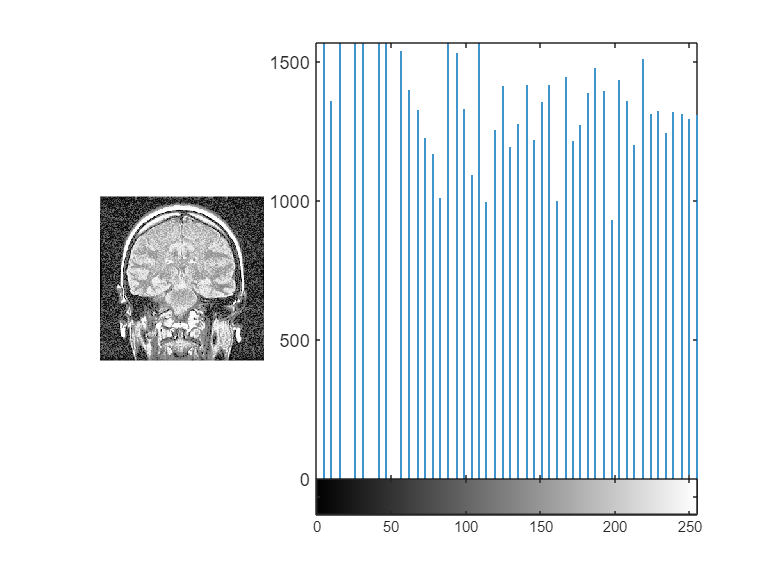

Eq_MRI_cust = histeq(Gmr.GrayScaleMRI,nbins_sb);
figure('Name','Histogram Equalization with Customizable Number of Bins')
subplot(1,3,1)
imshow(Eq_MRI_cust)
subplot(1,3,2:3)
imhist(Eq_MRI_cust)

Additional Work: Let's suppose if we want to equalize our image as per the targeted histogram then we can also provide the targeted values and adjust image darkness intensity as per the targeted requirements.

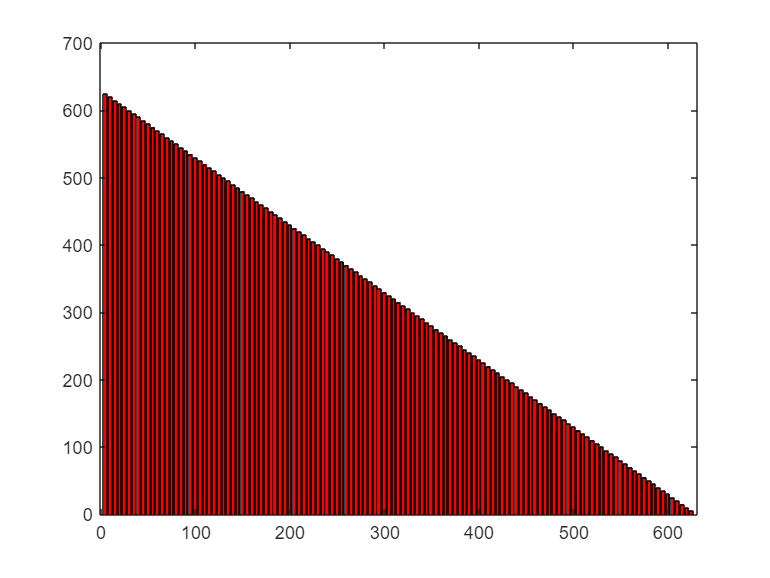

target_sb = 625:-5:5;
figure('Name','Target Histogram')
bar(5:5:625,target_sb,'red')

Adjusting my histogram of default image to approximately match the target histogram.

Eq_MRI_trgt = histeq(Gmr.GrayScaleMRI,target_sb);

Displaying the contrast-adjusted image as per the required target and its new required histogram.

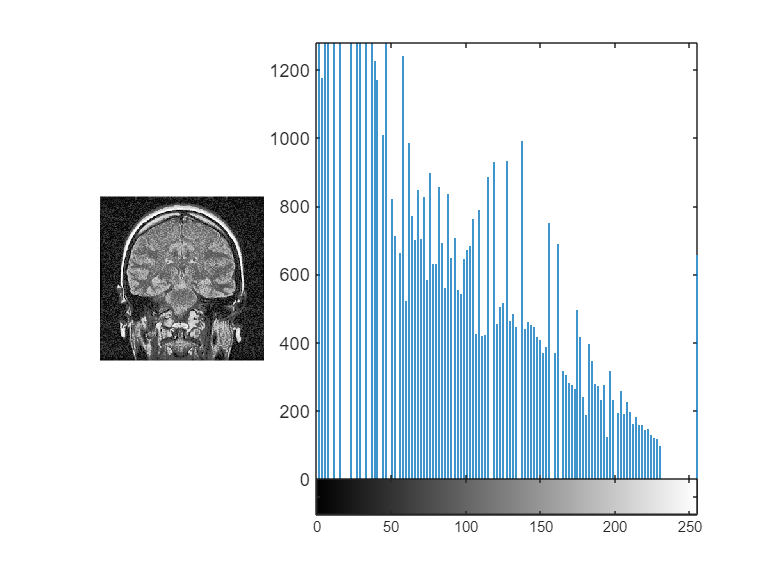

figure('Name','Targeted Histogam Display')
subplot(1,3,1)
imshow(Eq_MRI_trgt)
subplot(1,3,2:3)
imhist(Eq_MRI_trgt)